clear clean;
clc;


%%  Generate the training data
TRANS = [.9 .1; .05 .95;];
EMIS = [1/6, 1/6, 1/6, 1/6, 1/6, 1/6;7/12, 1/12, 1/12, 1/12, 1/12, 1/12];

len_seq = 100; % the length of one emission sequence
num_seq = 1000; % the number of emission sequence for training

seq_M=zeros(num_seq,len_seq);% the matrix for the emission sequence
states_M = zeros(num_seq,len_seq);% the states for the emission sequence(baseline) 

likelystates = zeros(num_seq,len_seq);% the predict states for specific emission sequence

%generate some HMM data with labels
for i=1:1:num_seq
[seq,states] = HMM_data(len_seq,TRANS,EMIS);
seq_M(i,:) = seq;
states_M(i,:) = states;
end


%% Train the parameters using the emission states

[TRANS_est,EMIS_est] = HMM_train(seq_M,0,states_M);

for i=1:1:num_seq
[seq,states] = HMM_data(len_seq,TRANS_est,EMIS_est);
seq_M(i,:) = seq;
states_M(i,:) = states;
end



%% Predict the states of the functions

probs=zeros(1,num_seq);
for i=1:1:num_seq
[likelystates(i,:),probs(1,i)] = HMM_predict(TRANS_est,EMIS_est,seq_M(i,:),states_M(i,:));
end

probs_1=zeros(1,num_seq);
for i=1:1:num_seq
[likelystates(i,:),probs_1(1,i)] = HMM_predict(TRANS,EMIS,seq_M(i,:),states_M(i,:));
end

for i=1:1:num_seq
[seq,states] = HMM_data(len_seq,TRANS_est,EMIS_est);
seq_M(i,:) = seq;
states_M(i,:) = states;
end


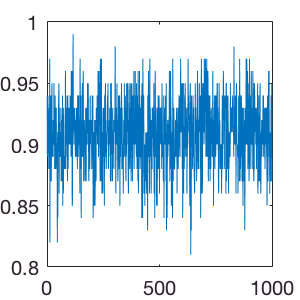

%% Visualize the result
figure('position',[50 50 150 150]);
plot(probs);